# 数据分析与机器学习案例

        本案例基于泰坦尼克号事件数据，介绍如何使用Matlab对相关数据进行分析与处理，建立泰坦尼克号乘客是否幸存的预测模型。

        内容仅涉及对数据的讨论，不就事件本身性质以及影响等做任何研究。

#     愿灾难不再发生🕯

———————————————————————————————————————————————————————

# 正文

## 0.相关内容

- Matlab对象

- table变量

- cell变量

- nan系列数学运算函数 not a number  nanmean

- statistics and machine learning toolbox

## 1.数据导入与展示

data = readtable('train.csv');%table
[row,col] = size(data);
head(data)

ans = 8×12 table
    PassengerId    Survived    Pclass                            Name                               Sex       Age    SibSp    Parch          Ticket           Fare     Cabin     Embarked
    ___________    ________    ______    _____________________________________________________    ________    ___    _____    _____    __________________    ______    ______    ________

         1            0          3       'Braund, Mr. Owen Harris'                                'male'       22      1        0      'A/5 21171'             7.25    ''          'S'   
         2            1          1       'Cumings, Mrs. John Bradley (Florence Briggs Thayer)'    'female'     38      1        0      'PC 17599'            71.283    'C85'       'C'   
         3            1          3       'Heikkinen, Miss. Laina'                                 'female'     26      0        0      'STON/O2. 3101282'     7.925    ''          'S'   
         4            1          1       'Futrelle, 

varnames = data.Properties.VariableNames

varnames = 1×12 cell 数组
    {'PassengerId'}    {'Survived'}    {'Pclass'}    {'Name'}    {'Sex'}    {'Age'}    {'SibSp'}    {'Parch'}    {'Ticket'}    {'Fare'}    {'Cabin'}    {'Embarked'}


**各个特征的中文名**

**PassengerId 乘客编号**

**Survived       存活情况**

**Pclass           客舱等级**

**Name            乘客姓名**

**Sex                性别**

**Age                年龄**

**SibSp             同乘的兄弟姐妹/配偶数**

**Parch             同乘的父母/小孩数**

**Ticket             船票编号**

**Fare                船票价格**

**Cabin              客舱号**

**Embarked      登船港口**

## 2.补全缺失值

for name = varnames %age
    tempdata = data(:,name).Variables;
    %若为数值类型数据缺失，则以该列众数进行填补
    if isnumeric(tempdata)
        nanindex = isnan(tempdata);
        if sum(nanindex) %>0
            com = tsnanmode(tempdata);
            tempdata(nanindex) = com;
        end
        data(:,name).Variables = tempdata;
    %若为字符串类型数据缺失，则以该列出现次数最多的字符串进行填补
    else
        nanindex = cellfun(@(x) isempty(x),tempdata);
        if sum(nanindex)
            index = find(nanindex);
            %tabulate函数对单组数据的模式进行统计
            sat = tabulate(tempdata);
            count_arr = [sat{:,2}];
            [~,max_freq_index] = max(count_arr);
            mode_ = tempdata{max_freq_index};
            for i = 1:length(index)
                tempdata{index(i)} = mode_;
            end
        end
        data(:,name).Variables = tempdata;
    end
end

## 3.特征工程

### 3.1 清除明显的无关特征

        明显的无关特征包括Name,PassengerId,Ticket,Cabin

        删除Cabin的原因是该列缺失数据过多，达到687个，超过77%。 

remove_set = {'PassengerId','Name','Ticket','Cabin'};
result_set = setdiff(varnames,remove_set);
data = data(:,result_set);

### 3.2 特征选择

#### 3.2.1 对性别数据与登船港口号数据进行编码     

%对性别进行编码
m_index = cellfun(@(x) isequal(x,'male'),data(:,'Sex').Variables);
f_index = cellfun(@(x) isequal(x,'female'),data(:,'Sex').Variables);
data(m_index,'Sex').Variables = repmat({1},sum(m_index),1);%[1 1 1 1 1]
data(f_index,'Sex').Variables = repmat({2},sum(f_index),1);
%对登船港口进行编码
C_index = cellfun(@(x) isequal(x,'C'),data(:,'Embarked').Variables);
Q_index = cellfun(@(x) isequal(x,'Q'),data(:,'Embarked').Variables);
S_index = cellfun(@(x) isequal(x,'S'),data(:,'Embarked').Variables);

data(C_index,'Embarked').Variables = repmat({1},sum(C_index),1);
data(Q_index,'Embarked').Variables = repmat({2},sum(Q_index),1);
data(S_index,'Embarked').Variables = repmat({3},sum(S_index),1);

Embarked = cell2mat(data(:,'Embarked').Variables);
Sex = cell2mat(data(:,'Sex').Variables);
%由于table变量各列数据类型不好变化，因此选择删除后重新建立的方法
data.Embarked = [];
data.Sex = [];
data = addvars(data,Embarked,'Before','Survived');
data = addvars(data,Sex,'Before','Survived');

#### 3.2.2 对剩余数据进行特征选择

rng(0);
Y = data(:,'Survived').Variables;
X = data(:,setdiff(result_set,'Survived')).Variables;
%近邻成分分析——Neighbourhood Component Analysis(NCA)
%fscnca——feature selection using neighborhood component analysis for classification
mdl = fscnca(X,Y);

    [近邻成分分析理论部分参考链接](https://zhuanlan.zhihu.com/p/48371593)

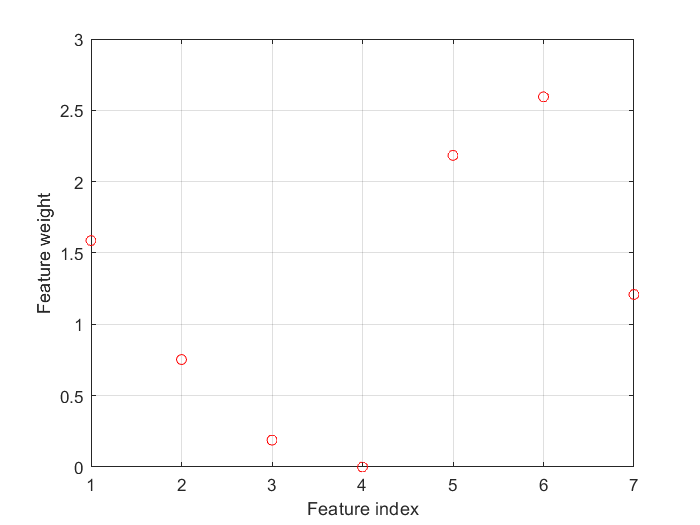

figure()
plot(mdl.FeatureWeights,'ro');
grid on
xlabel('Feature index');
ylabel('Feature weight');

根据上图权重值，取较好的第1，5，6，7个特征

此处也可选取阈值为0.5或者1，尝试使用不同的特征选择结果来训练模型

feature_selection_index = [1,5,6,7];
feature_selection = {data.Properties.VariableNames{feature_selection_index}};

## 4.预测模型建立及其在训练集上的表现

### 4.1 支持向量机分类

inp = data(:,feature_selection).Variables;
labels = data(:,'Survived').Variables;
model = fitcsvm(inp,labels,'KernelFunction','RBF');
cvmodel = crossval(model,'kfold',10);
cvloss = kfoldLoss(cvmodel)

cvloss = 0.2480

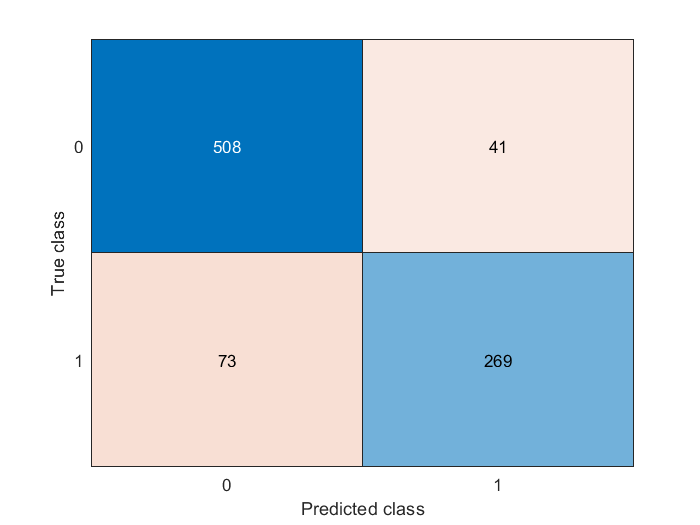

data_prediction = predict(model,inp);
res = confusionchart(labels,data_prediction);

resdata = res.NormalizedValues;
TP = resdata(2,2);
TN = resdata(1,1);
FP = resdata(1,2);
FN = resdata(2,1);
precision = TP/(TP+FP)

precision = 0.8677

recall = TP/(TP+FN)

recall = 0.7865

F1 = 2*precision*recall/(precision+recall)

F1 = 0.8252

### 4.2 最近邻分类

model_ = fitcknn(inp,labels);
cvmodel_ = crossval(model_,'kfold',10);
cvloss_ = kfoldLoss(cvmodel_)

cvloss_ = 0.3513

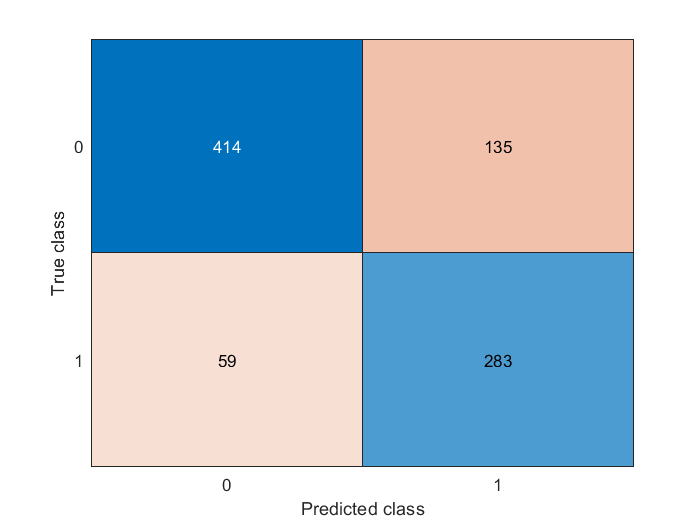

data_prediction_ = predict(model_,inp);
res_ = confusionchart(labels,data_prediction_);

resdata_ = res_.NormalizedValues;
TP_ = resdata_(2,2);
TN_ = resdata_(1,1);
FP_ = resdata_(1,2);
FN_ = resdata_(2,1);
precision_ = TP_/(TP_+FP_)

precision_ = 0.6770

recall_ = TP_/(TP_+FN_)

recall_ = 0.8275

F1_ = 2*precision_*recall_/(precision_+recall_)

F1_ = 0.7447

## 5.预测模型建立及其在测试集上的表现(仅svm)

### 5.1 测试集的预处理

data_ = readtable('test.csv');%测试集样本数据
labels_ = readtable('gender_submission.csv');%测试集标签数据
[row_,col_] = size(data_);
head(data_)

ans = 8×11 table
    PassengerId    Pclass                         Name                           Sex       Age     SibSp    Parch     Ticket       Fare     Cabin    Embarked
    ___________    ______    ______________________________________________    ________    ____    _____    _____    _________    ______    _____    ________

        892          3       'Kelly, Mr. James'                                'male'      34.5      0        0      '330911'     7.8292     ''        'Q'   
        893          3       'Wilkes, Mrs. James (Ellen Needs)'                'female'      47      1        0      '363272'          7     ''        'S'   
        894          2       'Myles, Mr. Thomas Francis'                       'male'        62      0        0      '240276'     9.6875     ''        'Q'   
        895          3       'Wirz, Mr. Albert'                                'male'        27      0        0      '315154'     8.6625     ''        'S'   
        896          3       'Hirv

head(labels_)

ans = 8×2 table
    PassengerId    Survived
    ___________    ________

        892           0    
        893           1    
        894           0    
        895           0    
        896           1    
        897           0    
        898           1    
        899           0    


#### 5.1.1 补全所选特征的缺失值

for name = feature_selection
    tempdata = data_(:,name).Variables;
    %若为数值类型数据缺失，则以该列众数进行填补
    if isnumeric(tempdata)
        nanindex = isnan(tempdata);
        if sum(nanindex)
            com = tsnanmode(tempdata);
            tempdata(nanindex) = com;
        end
        data_(:,name).Variables = tempdata;
    %若为字符串类型数据缺失，则以该列出现次数最多的字符串进行填补
    else
        nanindex = cellfun(@(x) isempty(x),tempdata);
        if sum(nanindex)
            index = find(nanindex);
            sat = tabulate(tempdata);
            count_arr = [sat{:,2}];
            [~,max_freq_index] = max(count_arr);
            mode_ = tempdata{max_freq_index};
            for i = 1:length(index)
                tempdata{index(i)} = mode_;
            end
        end
        data_(:,name).Variables = tempdata;
    end
end

#### 5.1.2 数据编码

%对性别进行编码
m_index = cellfun(@(x) isequal(x,'male'),data_(:,'Sex').Variables);
f_index = cellfun(@(x) isequal(x,'female'),data_(:,'Sex').Variables);
data_(m_index,'Sex').Variables = repmat({1},sum(m_index),1);
data_(f_index,'Sex').Variables = repmat({2},sum(f_index),1);
%对登船港口进行编码
C_index = cellfun(@(x) isequal(x,'C'),data_(:,'Embarked').Variables);
Q_index = cellfun(@(x) isequal(x,'Q'),data_(:,'Embarked').Variables);
S_index = cellfun(@(x) isequal(x,'S'),data_(:,'Embarked').Variables);

data_(C_index,'Embarked').Variables = repmat({1},sum(C_index),1);
data_(Q_index,'Embarked').Variables = repmat({2},sum(Q_index),1);
data_(S_index,'Embarked').Variables = repmat({3},sum(S_index),1);

Embarked = cell2mat(data_(:,'Embarked').Variables);
Sex = cell2mat(data_(:,'Sex').Variables);
%由于table变量各列数据类型不好变化，直接赋值为double数据会报错（can not cell2double），因此选择删除后重新建立的方法
data_.Embarked = [];
data_.Sex = [];
data_ = addvars(data_,Embarked);
data_ = addvars(data_,Sex);

### 5.2 模型测试

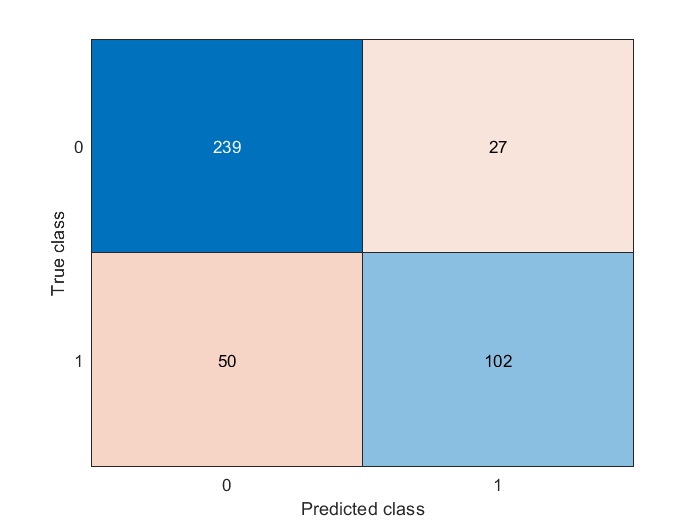

inp_test = data_(:,feature_selection).Variables;
labels_test = labels_(:,'Survived').Variables;
data_prediction_test = predict(model,inp_test);
res_test = confusionchart(labels_test,data_prediction_test);

resdata_test = res_test.NormalizedValues;
TP_test = resdata_test(2,2);
TN_test = resdata_test(1,1);
FP_test = resdata_test(1,2);
FN_test = resdata_test(2,1);
precision_test = TP_test/(TP_test+FP_test)

precision_test = 0.7907

recall_test = TP_test/(TP_test+FN_test)

recall_test = 0.6711

F1_test = 2*precision_test*recall_test/(precision_test+recall_test)

F1_test = 0.7260